# Stochastic Subspace Identification of a Vibrating String

This example demonstrates covariance-based Stochastic Subspace Identification (SSI) as well as covariance-based SSI with reference sensors (SSI-cov/ref) using functions included in the OoMA toolbox for transverse vibration of taut string.

## Taut String Simulation

Simulate the motion of a string impulsed at the center using the function `stringFDTD` that is included with the OoMA toolbox.

T = 100; % string tension
x = linspace(0,0.25,20); % string spatial discretization vector
rho = 0.1; % string mass per unit length
c = 1; % viscous damping coefficient
td = 1; % time duration to simulate
f_idx = round(length(x)/2); % force (impulse) applied at center
[y,t] = stringFDTD(T,x,rho,c,td,f_idx);

Plot the time history of the string motion.

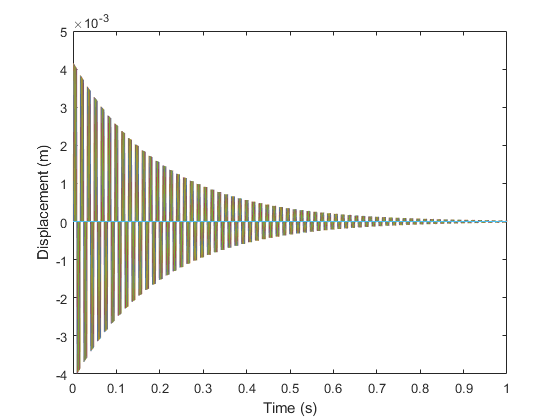

clf
plot(t,y)
xlabel('Time (s)')
ylabel('Displacement (m)')

The influence of damping is apparent in the exponential decay of the string motion after the impulse is applied.

## Complex Mode Indicator Function

Create the Complex Mode Indicator Function (CMIF) from the output time history using the function `cmif` included in the OoMA toolbox and plot the first three components to visualize the frequency content of the signal.

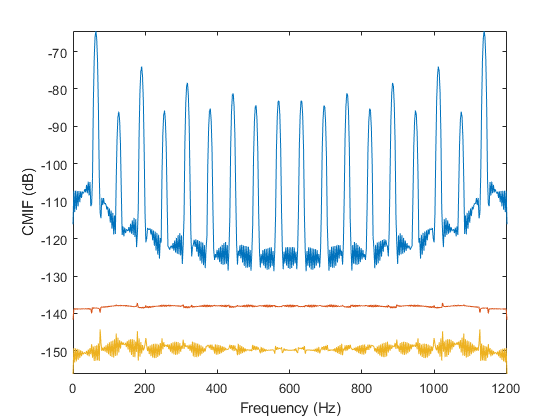

dt = t(2)-t(1);
[SV,F] = cmif(y,[],dt);
clf
plot(F,10*log10(SV(1:3,:)))
axis tight
xlabel('Frequency (Hz)')
ylabel('CMIF (dB)')

The CMIF displays many peaks (~18) in the power spectrum. The first component (blue) appears to dominate the response at all frequencies. The number of peaks (18) corresponds to the degrees of freedom in the simulated system (20 minus the two endpoints).

## Stochastic Subspace Identification

Run `ssicov` on the output data.

order = 50;
s = 2*order;
[A,C,G,R0] = ssicov(y,order,s);

SSI-cov status:
  forming block Hankel matrix...
  performing singular value decomposition...
  generating system matrices A,C,G for 50 model orders...
SSI-cov finished.


Create the stabilization diagram from the identified systems.

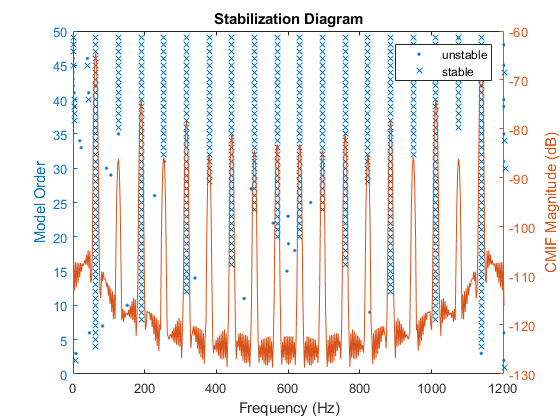

IDs = plotstab(A,C,y,dt,[],[.01 .05 .98]);

The stabilization diagram overlays the first component of the CMIF onto the stable pole alignments. Model order 36 appears to be the lowest order that contains every pole alignment shown in the stabilization diagram.

Draw the first five mode shapes from the identified system.

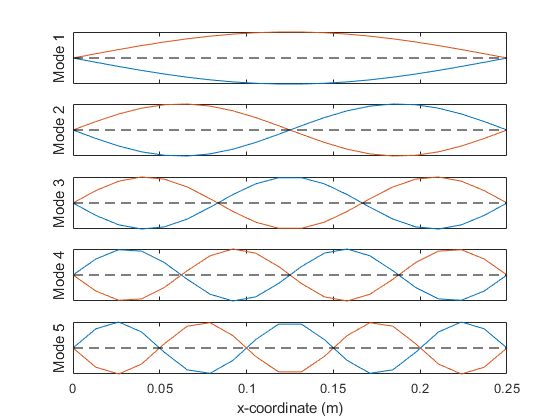

[f,psi,Phi] = modalparams(A,C,dt);
sel_order = 36;
n_modes = 5;
clf
for i = 1:n_modes
    subplot(n_modes,1,i)
    z = Phi{sel_order}(:,i);
    plot(x,abs(z).*cos(angle(z)))
    hold on
    plot(x,-abs(z).*cos(angle(z)))
    line([x(1) x(end)],[0 0],'color','k','linestyle','--')
    hold off
    yticks([])
    if i ~= n_modes
        xticklabels([])
    else
        xlabel('x-coordinate (m)')
    end
    ylabel(['Mode ' num2str(i)])
    axis tight
end

Here we see typical mode shapes of a taut transversely vibrating string that have been obtained from output-only data from a numerical model - no model for the system has been assumed other than that it is a linear system.

## Reference-based SSI

Now let's try a reference-based SSI method called SSI-cov/ref. Impulse the string at several arbitrary locations and select the same four points as reference sensors. Use a moving pool of 4 sensors in 4 different setups to generate the complete set of output data.

The string is discretized into 20 locations, choose four at random to be the reference sensors. Successivley choose 4 sets of 4 sensors at random (without replacement) for the moving sensors which will correspond to 4 different measurement trials. For reach sensor setup, impulse the string at 3 random locations and concatenate the output data. The reference-based SSI function `ssicovref` requires an array of structures as input, where the data from the reference and moving sensor pools are separated.

sensor_ids = randperm(length(x));
ref_ids = sensor_ids(1:4);
mov_ids = zeros(4,4);
rng(1) % control the random seed for repeatable results
for i = 1:4
    mov_ids(i,:) = sensor_ids(4+(i-1)*4+1:4+i*4);
end
Y = struct([]);
for i = 1:4
    ref = [];
    mov = [];
    for j = 1:3 % three random impulse locations for each sensor setup
        f_idx = randi(length(x)-2)+1; % force (impulse) applied at random location that isnt the endpoints
        [y,t] = stringFDTD(T,x,rho,c,td,f_idx);
        ref = [ref y(ref_ids,:)];
        mov = [mov y(mov_ids(i,:),:)];
    end
    % create the data structure entries corresponding to this measurement setup
    Y(i).ref = ref;
    Y(i).mov = mov;
end

With the data generated, time to call `ssicovref`.

order = 50;
s = 2*order;
[A_ref,C_ref] = ssicovref(Y,order,s);

SSI-cov/ref status:
  processing setup 1 of 4...
  processing setup 2 of 4...
  processing setup 3 of 4...
  processing setup 4 of 4...
  generating global observability matrix...
  generating system matrices A,C for 50 model orders...
SSI-cov/ref finished.


Generate the stabilization diagram to help select an appropriate model order.

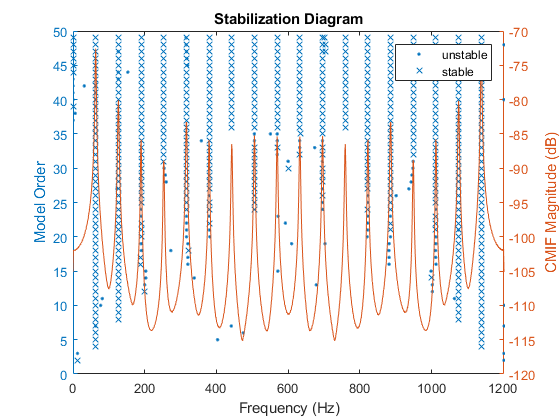

err = [0.1,0.05,0.98];
IDs_ref = plotstab(A_ref,C_ref,Y(1).ref,dt,[],err);

Let's grab the system at model order 36 as before and plot some modes. Since the sensor locations were randomized, they will need to be sorted by position to draw the mode shapes. Also note that `ssicovref` structures its output such that they are ordered with reference sensors first followed by the moving sensors, ordered by setup number.

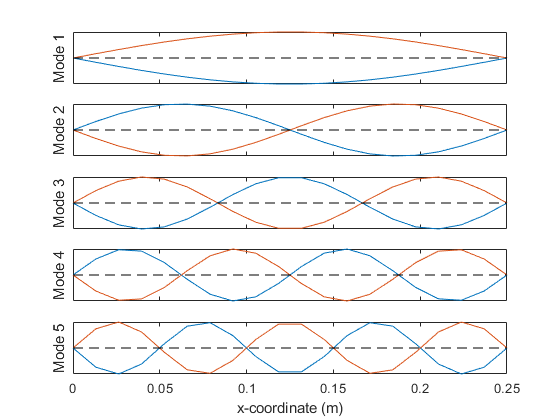

[f_ref,psi_ref,Phi_ref] = modalparams(A_ref,C_ref,dt);
sel_order = 36;
n_modes = 5;
[~,I] = sort(sensor_ids); % sorting vector
clf
for i = 1:n_modes
    subplot(n_modes,1,i)
    z = Phi_ref{sel_order}(I,i); % reorders using vector I
    plot(x,abs(z).*cos(angle(z)))
    hold on
    plot(x,-abs(z).*cos(angle(z)))
    line([x(1) x(end)],[0 0],'color','k','linestyle','--')
    hold off
    yticks([])
    if i ~= n_modes
        xticklabels([])
    else
        xlabel('x-coordinate (m)')
    end
    ylabel(['Mode ' num2str(i)])
    axis tight
end

The mode shapes are similar to the results obtained from the non-reference-based SSI-cov algorithm.

Let's check the mode shape similarities using the function `macplot`. The mode shape vectors will need to be sorted again according to the random sensor placements.

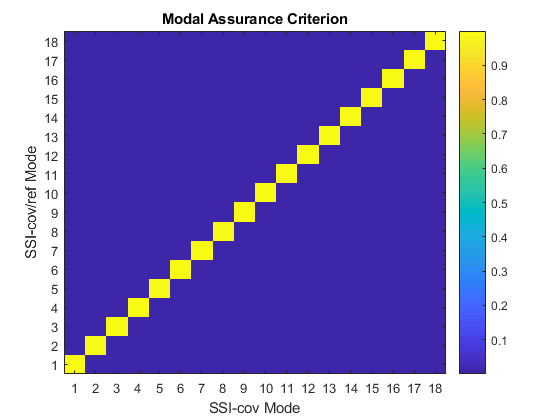

mm = macmatrix(Phi{sel_order}(:,IDs{sel_order}),Phi_ref{sel_order}(I,IDs_ref{sel_order}));
macplot(mm)
xlabel('SSI-cov Mode')
ylabel('SSI-cov/ref Mode')

We see effectively perfect agreement between the two sets of mode shapes.

## Concluding Remarks

Reference-based SSI is useful when there is a limited number of sensors available and the potential number of degrees of freedom of the system is large. As we see in this example, the reference-based method used in the OoMA toolbox function `ssicovref` produces equivalent mode shape estimates when compared to using a non-reference based method (SSI-cov) on the full set of data. However, (in its current state) estimates of the zero-lag output covariances $\mathbf{R}_0$ and the next state output covariance matrix $\mathbf{G}$ are not available from the reference-based algorithm, which prevents generation of identified output spectrums $S_{yy}(z)$.